clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',true,'Display','iter','FunctionTolerance',1e-4,'MaxFunctionEvaluations',150);

tic
[xv,Rv] = fmincon(@(x) objective(x),[0.5 0.9 1.6 0.4 10 8],[],[],[],[],[0 0 0 0 0 0],[3 3 3 3 100 100],[],opts)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.823560e+02    0.000e+00    1.055e+02
    1       2    1.280793e+02    0.000e+00    2.346e+02    2.757e+00
    2       3    9.218199e+01    0.000e+00    8.507e+01    4.490e-01
    3       5    6.893096e+01    0.000e+00    7.753e+03    1.402e+00
    4       7    6.488032e+00    0.000e+00    2.872e+02    2.905e+00
    5      10    5.910660e+00    0.000e+00    3.405e+02    1.682e+00
    6      18    5.431188e+00    0.000e+00    2.312e+02    4.342e-01
    7      20    1.978870e+00    0.000e+00    1.397e+02    4.459e-01
    8      28    1.880376e-01    0.000e+00    2.864e+00    8.612e-02
    9      30    1.865631e-01    0.000e+00    2.697e+00    1.374e-03
   10      38    1.139696e-01    0.000e+00    7.416e+00    5.544e-02
   11      46    7.889703e-02    0.000e+00    1.017e+01    4.844e-02
   12      52    9.359117e-03    0.000e+00    9

xv =     2.9980    0.4889    2.2652    0.2681   11.4885    9.5350


Rv = 4.1672e-06

toc

Elapsed time is 142.742800 seconds.


xv

xv =     2.9980    0.4889    2.2652    0.2681   11.4885    9.5350



A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.PredatorPreyRHS(t,y,A(1),A(2),A(3),A(4)), [A(5);A(6)], 0, 10, 0.01,  1e-9, A);
toc

Elapsed time is 3.619046 seconds.



L = sum((yf{end} - [10;10]).^2);

dL = full(getderivs(L))

dL =    -1.8640   12.2257   -0.6722    4.0985    0.5128    0.8114


L = getvalue(L)

L = 0.0086


yfv=[];
dyfv=[];

for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end


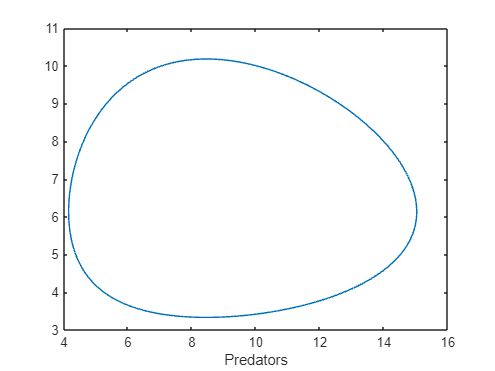

figure
plot(yfv(1,:),yfv(2,:))
xlabel('Prey')
xlabel('Predators')

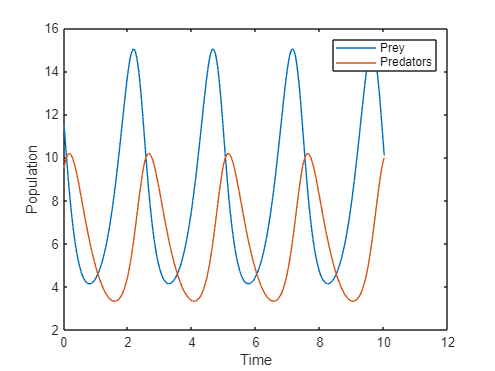


figure
plot(tf,yfv(1,:))
hold on
plot(tf,yfv(2,:))
xlabel('Time')
ylabel('Population')
legend('Prey','Predators')

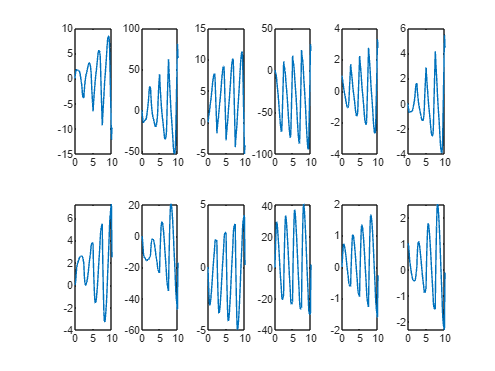


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L,dL] = objective(x)

A = AutoDiff([x(1) x(2) x(3) x(4) x(5) x(6)]);

[~, yf] = ODE.rkf45(@(t,y) ODE.test.PredatorPreyRHS(t,y,A(1),A(2),A(3), A(4)), [A(5);A(6)], 0, 10, 0.01,1e-6, A);

L = sum((yf{end} - [10;10]).^2);

dL = full(getderivs(L));
L = getvalue(L);

end